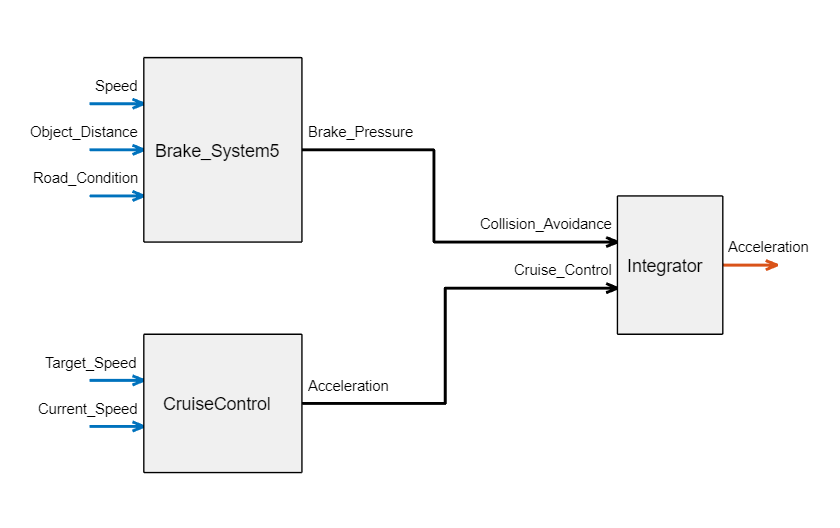

Brakes = readfis("Brake_System5.fis");
CruiseControl = readfis("CruiseControl.fis");
PedalIntegrator = readfis("PedalIntegrator.fis");

incConnection = ["Brake_System5/Brake_Pressure" "Integrator/Collision_Avoidance"];
slopeConnection = ["CruiseControl/Acceleration" "Integrator/Cruise_Control"];

fuzzTree = fistree([Brakes CruiseControl PedalIntegrator], [incConnection;slopeConnection]);
plotfis(fuzzTree)